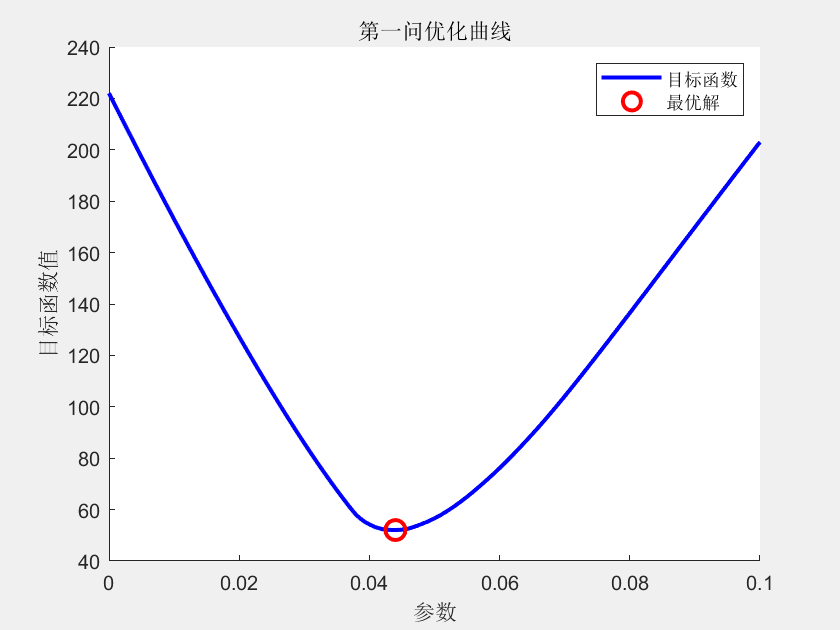

clc,clear
d=0.6;                               %单根纤维的直径  mm 
h=2*d;                                    %织物的厚度  mm
T_end=0.1;                          
m = 0;              
x = linspace(0,h,50);                     %单位 mm                         
t =linspace(0,T_end,50);                  %单位s
mark=0;
sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,[],mark),@pdex1ic,@pdex1bc,x,t);
u1 = sol(:,:,1);

%优化
x_lb=0;
x_ub=0.1;
param_range = x_lb:0.001:x_ub;
% %计算目标函数值
objective_values = zeros(size(param_range));
for i = 1:length(param_range)
    objective_values(i) = Obj_fun(param_range(i),u1);
end
%绘制曲线
plot(param_range, objective_values, 'b-', 'LineWidth', 2);
hold on;
[best_value, best_index] = min(objective_values);
best_param = param_range(best_index);
plot(best_param, best_value, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
title('第一问优化曲线');
xlabel('参数');
ylabel('目标函数值');
legend('目标函数', '最优解');


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              10           55.04           115.6        0
    1              20            53.3           150.3        0
    2              30           52.07             132        0
    3              40           52.07           116.2        1
    4              50           52.07           119.1        2
    5              60           52.07           143.2        3
    6              70           52.07             135        4
    7              80           52.07           126.1        5
    8              90           52.04           154.1        0
    9             100           52.04           132.5        1
   10             110           52.04           148.8        2
   11             120           52.04           110.3        3
   12             130           52.04           96.25        4
   13             140           52.04           

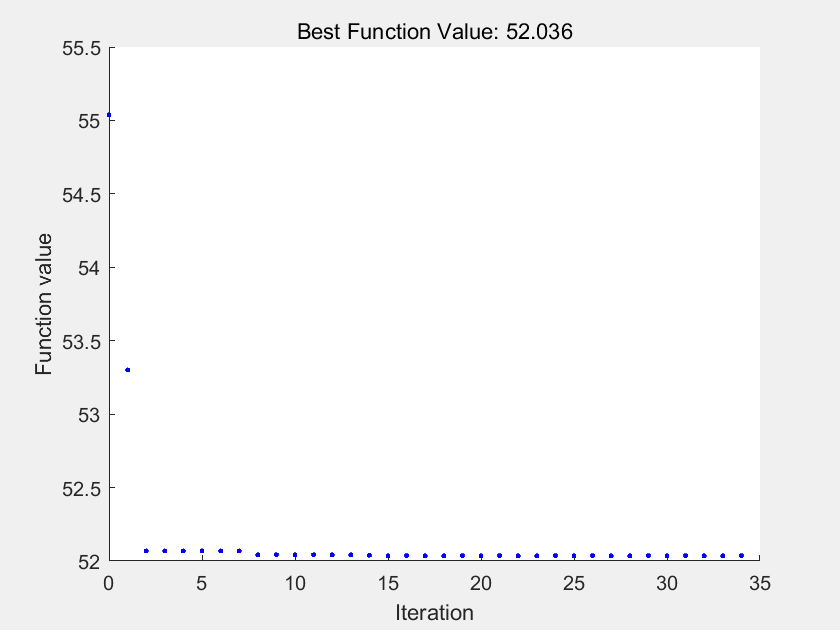

Switching to the hybrid optimization algorithm (FMINCON).
FMINCON ended.


x = 0.0437

fval = 52.0360

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 34
     funccount: 389
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.↵FMINCON: 可能存在局部最小值。满足约束。↵↵fmincon 已停止，因为当前步长小于↵步长容差值并且在约束容差值范围内满足约束。↵↵<停止条件详细信息>↵↵优化已停止，因为 x 的所有元素的相对变化↵小于 options.StepTolerance = 1.000000e-10，↵并且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。↵'
    hybridflag: 2


%粒子群算法
narvs=1;
options = optimoptions('particleswarm','MaxIterations',800,'Display','iter','PlotFcn','pswplotbestf','HybridFcn',@fmincon);  
[x,fval,exitflag,output] = particleswarm(@(k_fiber)Obj_fun(k_fiber,u1), narvs, x_lb, x_ub,options)  

function f=Obj_fun(k_fiber,u1)
    %initialize parameter
    %k_tol=0.03315;                              %热导率 W/(m·K)
    %k_air=0.0296;   
    %k_fiber=0.0473;
    d=0.6;                                    %单根纤维的直径  mm 
    h=2*d;                                    %织物的厚度  mm
    T_end=0.1;                          
    m = 0;              
    x = linspace(0,h,50);                     %单位 mm                        
    t =linspace(0,T_end,50);                  %单位s
    mark=1;
    sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,k_fiber,mark),@pdex1ic,@pdex1bc,x,t);
    u = sol(:,:,1);
    f=sum(sum(abs(u-u1)));
end
function [c,f,s] = pdex1pde(x,t,u,dudx,k_fiber,mark)
    cp=0.05;                                    %单位  Mj/m^3·K
    k_air=0.0296;                               %单位 W/(m·K)
    d=0.6;      
    theta_s=19.8/360*2*pi;                      %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                     %纬纱弯曲角度 rad
    a=10/6;                                     %1/rho_s       
    b=10/8;                                     %1/rho_w        
    S=a*b;                                      %单位 mm^2     
    S2=ca_S(x,d,theta_s,theta_w);       
    S1=S-S2;        
    if mark==1
        k_tol=(S1*k_air+S2*k_fiber)/S;          %截面热导率
    else 
        k_tol=0.033;
    end
    dT=0.9708905105832;
    P=(1/0.0296)*(0.033*dT)/(2*d);
    c=cp;
    f =k_tol*dudx;
    s = P*dirac_delta(x);
end
function S=ca_S(h,d,theta_s,theta_w)  
    if h>=d
        h=2*d-h;
    end
    if h<=d/2
    l=sqrt((d/2)^2-(d/2-h)^2);                  %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/pi-1/2*(d/2)^2*sin(2*thetas);
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/pi-1/2*(d/2)^2*sin(2*thetaw);
    S=(S_w/tan(theta_w)+S_s/tan(theta_s));
    elseif h>d/2
    theta_s=19.8/360*2*pi;                      %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                     %纬纱弯曲角度 rad
    l=sqrt((d/2)^2-(d/2-h)^2);                  %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/pi-1/2*(d/2)^2*sin(2*thetas);
    S_s=pi*(d/2)^2-S_s;
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/pi-1/2*(d/2)^2*sin(2*thetaw);
    S_w=pi*(d/2)^2-S_w;
    S=(S_w/tan(theta_w)+S_s/tan(theta_s));
    end
end
function u0 = pdex1ic(x)
    u0 = 298.15;
end
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)   
    d=0.6;
    dT=0.9708905105832;
    pl=(0.033*dT)/(2*d); 
    ql =0.0296;
    %pl=ul;
    %ql=0;
    pr = 0;
    qr = 1;
end
% 定义狄拉克δ函数
function d = dirac_delta(x)
    d = (abs(x) < 1e-9); % 使用一个小的范围来近似狄拉克δ函数
end
function u=L_Tight(t)
  p=[-59599.9047557005	14375.0113350970	-1218.80638780507	47.3729535516151	298.152007531907];
  u = p(1).*t.^4 + p(2).*t.^3 + p(3).*t.^2 + p(4).*t + p(5);
end
